# Examples for using the `newtons_method` function.

Copyright © 2021 Tamas Kis

## Example #1: Root of a simple function.

*Find the root of *$f\left(x\right)=x^2 -1$ *that is in the interval *$\left\lbrack 0,\infty \right)$.

For Newton's method, we also need $f^{\prime } \left(x\right)$. Differentiating $f\left(x\right)$,


$$f^{\prime } \left(x\right)=2x$$


Defining $f\left(x\right)$ and $f^{\prime } \left(x\right)$ in MATLAB,

f = @(x) x^2-1;
df = @(x) 2*x;

We want a root in the interval $\left\lbrack 0,\infty \right)$. Therefore, we use the initial guess $x_0 =10$. Finding this root using Newton's method,

root = newtons_method(f,df,10)

root = 1

## Example #2: Plot of intermediate root estimates.

*In example #1 we found the positive root of *$f\left(x\right)=x^2 -1$* using Newton's method. Now, produce a plot of the intermediate root estimates obtained by Newton's method before it returned the converged root.*

First, we define $f\left(x\right)$ and $f^{\prime } \left(x\right)$ in MATLAB like before.

f = @(x) x^2-1;
df = @(x) 2*x;

To obtain the intermediate root estimates, we simply need to call the `newtons_method` function with the optional input `'all'`.

intermediate_roots = newtons_method(f,df,10,[],[],'all');

Plotting the intermediate root estimates,

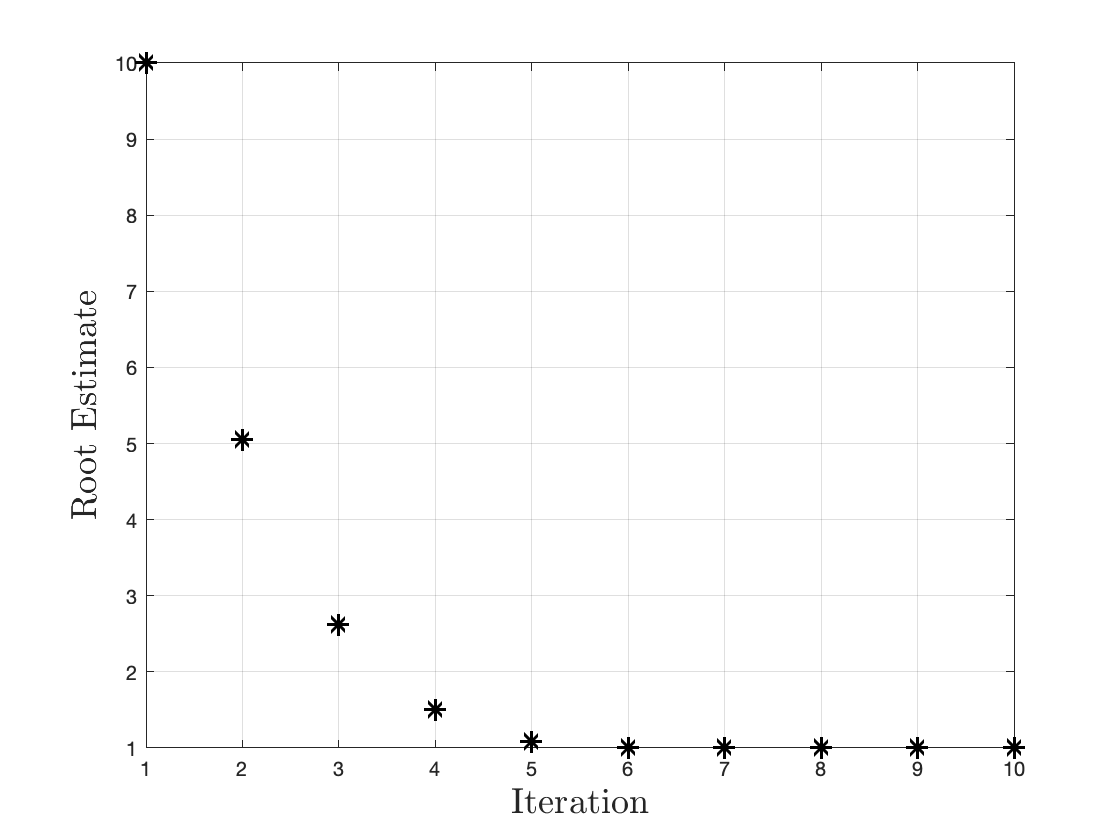

figure;
plot(intermediate_roots,'k*','markersize',9,'linewidth',1.5);
grid on;
xlabel('Iteration','interpreter','latex','fontsize',18);
ylabel('Root Estimate','interpreter','latex','fontsize',18);

We can also extract the converged root from `intermediate_roots`.

root = intermediate_roots(end)

root = 1